clear; close all;

% system
A = [0 1; -3 -4];
B = [0; 1];
C = [2 1];
s = tf('s');

% infinite gain margin, 85 degree phase margin
F = [50 10]; % optimal control law (2.1.22)
L_t = F*(s*eye(2)-A)^-1*B;
% margin(L_t)
bode(L_t); hold on;

% LTR - Bode Plot
for q2=[500,10^4,10^5]
% solve ARE to obtain K (2.1.18-19)
Q = q2*(B*B');
P = icare(A',C',Q)
K = P*C';

% Doyle-Stein LTR Procedure
L_o = F*(s*eye(2)-A+B*F+K*C)^-1*K*C*(s*eye(2)-A)^-1*B;
bode(L_o); 
end

P =     0.2441    0.3584
    0.3584   18.0776


P =     0.2497    0.4639
    0.4639   95.1753


P =     0.2500    0.4883
    0.4883  311.2842


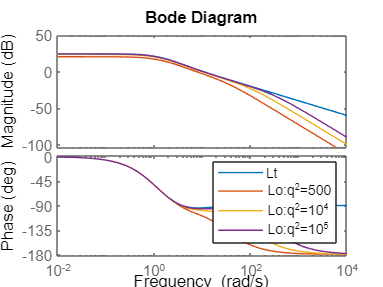

legend('Lt','Lo:q^2=500','Lo:q^2=10^4','Lo:q^2=10^5');
hold off;

% Nyquist plot
nyquist(L_t); hold on;

% LTR
for q2=[500,10^4,10^5]
% solve ARE to obtain K (2.1.18-19)
Q = q2*(B*B');
P = icare(A',C',Q)
K = P*C';

% Doyle-Stein LTR Procedure
L_o = F*(s*eye(2)-A+B*F+K*C)^-1*K*C*(s*eye(2)-A)^-1*B;
nyquist(L_o);
end

P =     0.2441    0.3584
    0.3584   18.0776


P =     0.2497    0.4639
    0.4639   95.1753


P =     0.2500    0.4883
    0.4883  311.2842


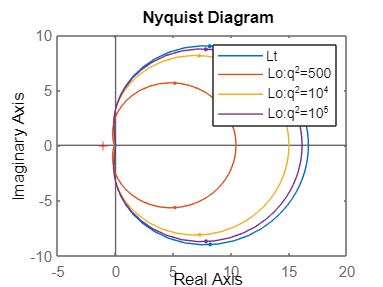


legend('Lt','Lo:q^2=500','Lo:q^2=10^4','Lo:q^2=10^5');
hold off;